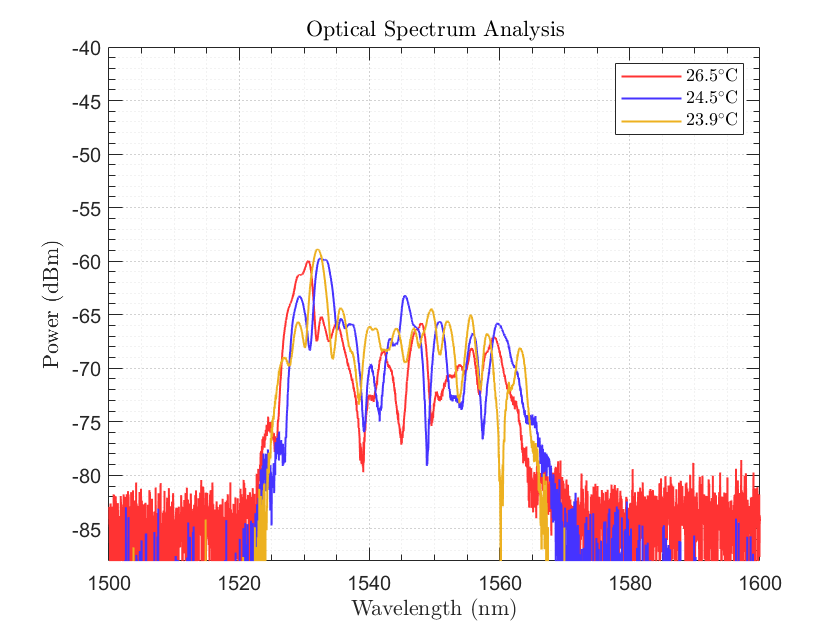

clear
clf
close all

cd 'C:\Users\glzdi\Documents\OpticsAndCV\PySciDevVS\src\Research\NonLinearFiberOptics\matlab\Data';% Trace B
% Trace F
% Read the data from the CSV file
data = readmatrix('C:\Users\glzdi\Documents\OpticsAndCV\PySciDevVS\src\Research\NonLinearFiberOptics\matlab\Data\W0039_265.CSV');

% Extract wavelength and power columns
wavelength = data(:, 1);
power = data(:, 2);

% Remove the first 21 elements from both vectors
wavelength(1:21) = [];
power(1:21) = [];

% Plot the remaining data
% tiledlayout(3,1)
% nexttile
plot(wavelength, power, "LineWidth", 1.02, 'DisplayName', '$26.5^{\circ}$C', 'Color', '#ff3333'); hold on
xlabel('Wavelength (nm)', "Interpreter","latex");
ylabel('Power (dBm)',"Interpreter","latex");
title('Optical Spectrum Analysis',"Interpreter","latex");
grid on
set(gca, 'XMinorTick', 'on', 'YMinorTick', 'on', ...
'TickLength', [0.02, 0.04], ...
'LineWidth', 0.5);
grid minor; % Adds minor grid lines
set(gca, 'GridLineStyle', ':', ...    % Dashed grid lines
         'GridColor', [0.5, 0.5, 0.5], ... % Gray grid lines
         'GridAlpha', 0.7, ...         % Transparency of major grid
         'MinorGridLineStyle', ':', ...% Dotted minor grid lines
         'MinorGridColor', [0.8, 0.8, 0.8], ... % Light gray minor grid
         'MinorGridAlpha', 0.5);       % Transparency of minor grid


% Trace G
% Read the data from the CSV file
data2 = readmatrix('C:\Users\glzdi\Documents\OpticsAndCV\PySciDevVS\src\Research\NonLinearFiberOptics\matlab\Data\W0040_245.CSV');

% Extract wavelength and power columns
wavelength2 = data2(:, 1);
power2 = data2(:, 2);

% Remove the first 21 elements from both vectors
wavelength2(1:21) = [];
power2(1:21) = [];

% Plot the remaining data
% figure;
plot(wavelength2, power2, "LineWidth", 1.02, 'DisplayName', '$24.5^{\circ}$C', 'Color', '#4633ff');
xlabel('Wavelength (nm)', "Interpreter","latex");
ylabel('Power (dBm)',"Interpreter","latex");
title('Optical Spectrum Analysis',"Interpreter","latex");
box on
grid on
set(gca, 'XMinorTick', 'on', 'YMinorTick', 'on', ...
'TickLength', [0.02, 0.04], ...
'LineWidth', 0.5);
grid minor; % Adds minor grid lines
set(gca, 'GridLineStyle', ':', ...    % Dashed grid lines
         'GridColor', [0.5, 0.5, 0.5], ... % Gray grid lines
         'GridAlpha', 0.7, ...         % Transparency of major grid
         'MinorGridLineStyle', ':', ...% Dotted minor grid lines
         'MinorGridColor', [0.8, 0.8, 0.8], ... % Light gray minor grid
         'MinorGridAlpha', 0.5);       % Transparency of minor grid
legend('Interpreter',"latex")

% 
% % Read the data from the CSV file
data3 = readmatrix('C:\Users\glzdi\Documents\OpticsAndCV\PySciDevVS\src\Research\NonLinearFiberOptics\matlab\Data\W0041_239.CSV');

% Extract wavelength and power columns
wavelength3 = data3(:, 1);
power3 = data3(:, 2);

% Remove the first 21 elements from both vectors
wavelength3(1:21) = [];
power3(1:21) = [];

% Trace B
% Plot the remaining data
% figure;
plot(wavelength3, power3, "LineWidth", 1.02, "DisplayName", '$23.9^{\circ}$C');
xlabel('Wavelength (nm)', "Interpreter","latex");
ylabel('Power (dBm)',"Interpreter","latex");
title('Optical Spectrum Analysis',"Interpreter","latex");
box on
grid on
set(gca, 'XMinorTick', 'on', 'YMinorTick', 'on', ...
'TickLength', [0.02, 0.04], ...
'LineWidth', 0.5);
grid minor; % Adds minor grid lines
set(gca, 'GridLineStyle', ':', ...    % Dashed grid lines
         'GridColor', [0.5, 0.5, 0.5], ... % Gray grid lines
         'GridAlpha', 0.7, ...         % Transparency of major grid
         'MinorGridLineStyle', ':', ...% Dotted minor grid lines
         'MinorGridColor', [0.8, 0.8, 0.8], ... % Light gray minor grid
         'MinorGridAlpha', 0.5);       % Transparency of minor grid

legend('Interpreter',"latex")
xlim([1500 1600])
ylim([-88 -40])